Q2: Finding equilibrium points:

syms g fv c m V L R y I 
eq1= -g+(c/m)*(I^2/(1-y))==0;
eq2= V/L - (R/L)*I==0;
solve([eq1,eq2],[I,V])

ans = struct with fields:
    I: [2×1 sym]
    V: [2×1 sym]


Answers: y=((g*m*(1-y))/c)^(1/2)

I=R*((g*m*(1-y))/c)^(1/2)

Q6: Finding root locus:

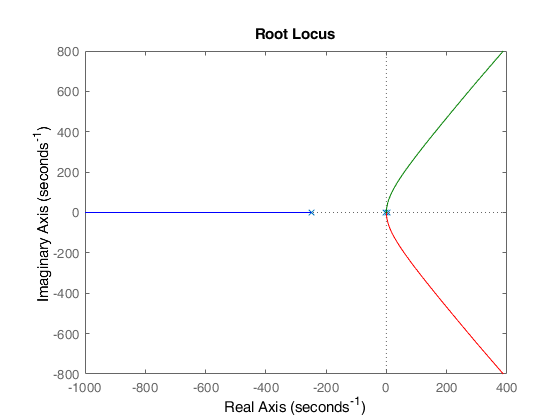

k=1;
s=tf('s');
G=633/(s^3+250.188*s^2+32.83*s-3542.5);
rlocus(G)

H=feedback(k*G,1)

H =
 
                633
  --------------------------------
  s^3 + 250.2 s^2 + 32.83 s - 2910
 
Continuous-time transfer function.



Q9: Desinging controller

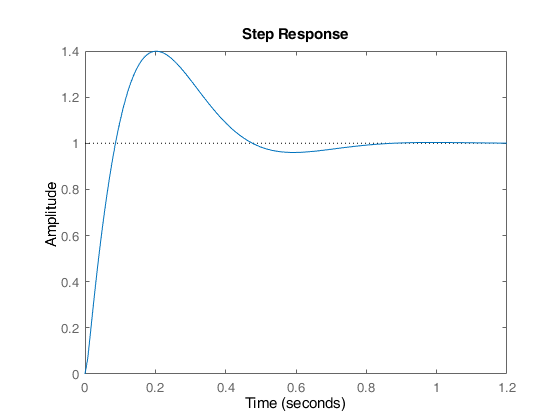

Gc=6.046*(s+4)*(s+6)/(s);
step(feedback(G*Gc,1))

stepinfo(feedback(G*Gc,1))

ans = struct with fields:
        RiseTime: 0.0650
    SettlingTime: 0.7300
     SettlingMin: 0.9215
     SettlingMax: 1.3991
       Overshoot: 39.9122
      Undershoot: 0
            Peak: 1.3991
        PeakTime: 0.2010


Q10

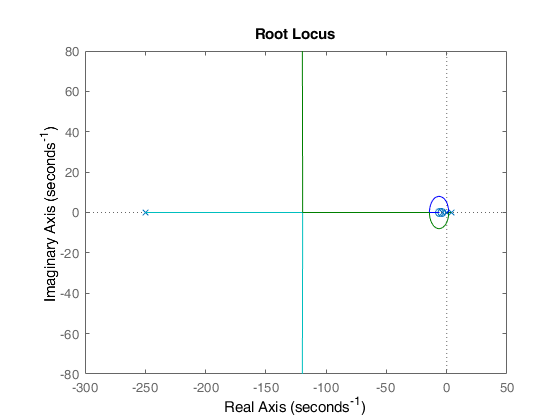

rlocus(G*Gc)